f = @(w) 0.4 .* w.^2 + 4 .* w + 11;

W = linspace(-20,20,1000);

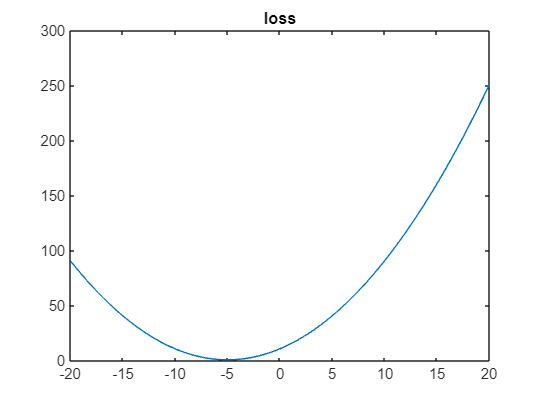

plot(W,f(W))
title("loss")

df = @(w) 0.8 .* w + 4;
d2f = @(w) 0.8 ;

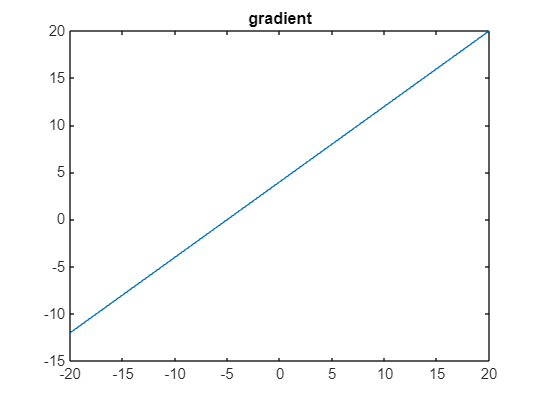

plot(W,df(W))
title("gradient")

w0 = 0;
mu = 1.5;
eps = 1e-3;

function w = SD(w0, mu, df, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step (Minimization is '-' mu * df)
        gradient = df(w(k));
        next_w = w(k) - mu * gradient;
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w_SD = SD(w0,mu,df,eps)

w_SD =          0   -6.0000   -4.8000   -5.0400   -4.9920   -5.0016   -4.9997   -5.0001


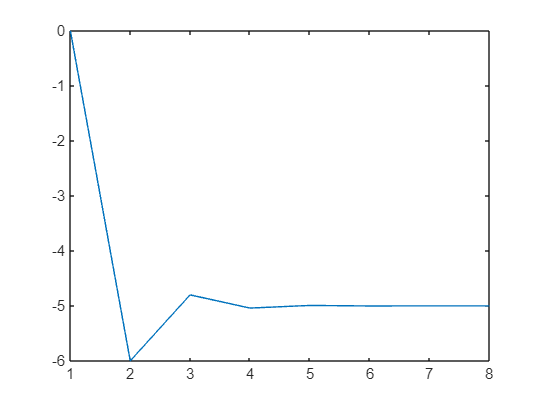

plot(1:length(w_SD),w_SD)

function w = Newton(w0, mu, df, d2f, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step (Minimization is '-' mu * df)
        next_w = w(k) - mu * df(w(k))/d2f(w(k));
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w_Newton = Newton(w0,mu,df,d2f,eps)

w_Newton =          0   -7.5000   -3.7500   -5.6250   -4.6875   -5.1562   -4.9219   -5.0391   -4.9805   -5.0098   -4.9951   -5.0024   -4.9988   -5.0006   -4.9997


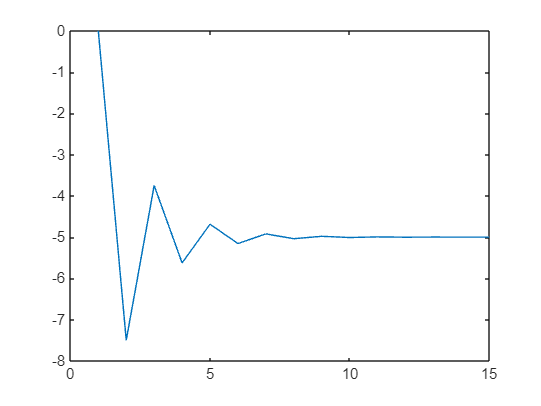

plot(1:length(w_Newton),w_Newton)

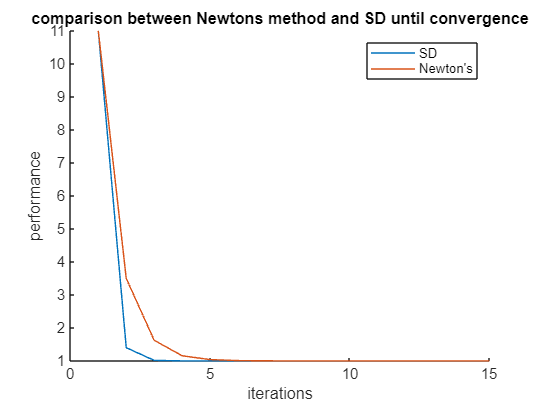

figure;
hold on ;

plot(1:length(w_SD),f(w_SD))
plot(1:length(w_Newton),f(w_Newton))
legend("SD","Newton's")
title("comparison between Newtons method and SD until convergence")
xlabel("iterations")
ylabel("performance")
hold off ; 